# `Audio Equalizer 3000™`

- Kyrollos Youssef    -    8057

- Mohab Sherif         -    8138

## User input

warning('off');
set(groot,'defaultAxesXGrid','on');
set(groot,'defaultAxesYGrid','on');

bands = [0 200; 200 400; 400 800; 800 1200; 1200 3e3; 3e3 6e3; 6e3 12e3; 12e3 15e3; 15e3 20e3];
gains = ones(height(bands),1);
min_gain = -20;
max_gain = 20;
file_in=      "/home/kiro/Projects/coleg/dsp/input_1.wav";
file_out=     "/home/kiro/Projects/coleg/dsp/output.wav";
filter_type = "iir";
gains(1) =-15.5;
gains(2) =-9.8;
gains(3) =14.2;
gains(4) =-10.8;
gains(5) =2.8;
gains(6) =-9.5;
gains(7) =4.6;
gains(8) =-16;
gains(9) =-10.6;
fs_dst = 32000;

 


Audio Player

 
stop(audio_obj);

if false
    resume(audio_obj);
else
    pause(audio_obj);
end

## Processing

gains_mul = 10 .^ (gains / 20);
[src, fs_src] = audioread(file_in);

src = resample(src, fs_dst, fs_src);
dst = zeros(length(src),1);

% bandpass doesn't handle low frequencies
dst = dst + gains_mul(1) * lowpass(src, bands(1, 2), fs_dst, ImpulseResponse=filter_type);

for i = 2 : height(bands)
    dst = dst + gains_mul(i) * bandpass(src, bands(i,:), fs_dst, ImpulseResponse=filter_type);
end
% Remove noise
% dst = lowpass(dst, fs_dst / 2 - 1, fs_dst);
audio_obj = audioplayer(dst, fs_dst);

dst = dst / max(dst);
audiowrite(file_out, dst, fs_dst);

## Plots

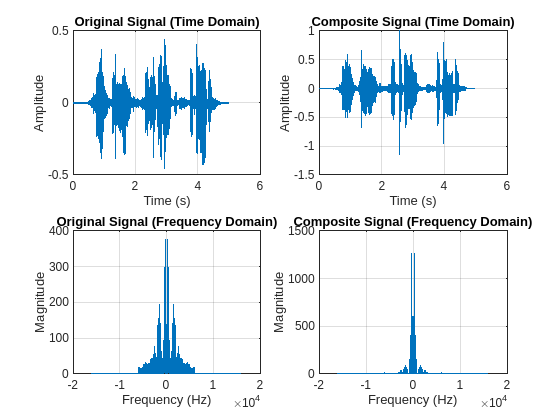

% Plot original signal in time domain
t_src = (0:length(src)-1) / fs_dst;
figure;
subplot(2,2,1);
plot(t_src, src);
xlabel('Time (s)');
ylabel('Amplitude');
title('Original Signal (Time Domain)');

% Plot composite signal in time domain
t_dst = (0:length(dst)-1) / fs_dst;
subplot(2,2,2);
plot(t_dst, dst);
xlabel('Time (s)');
ylabel('Amplitude');
title('Composite Signal (Time Domain)');

% Plot original signal in frequency domain
N_src = length(src);
f_src = (-N_src/2:N_src/2-1) * fs_dst / N_src;
Y_src = fftshift(abs(fft(src, N_src)));
subplot(2,2,3);
plot(f_src, Y_src);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Original Signal (Frequency Domain)');

% Plot composite signal in frequency domain
N_dst = length(dst);
f_dst = (-N_dst/2:N_dst/2-1) * fs_dst / N_dst;
Y_dst = fftshift(abs(fft(dst, N_dst)));
subplot(2,2,4);
plot(f_dst, Y_dst);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Composite Signal (Frequency Domain)');

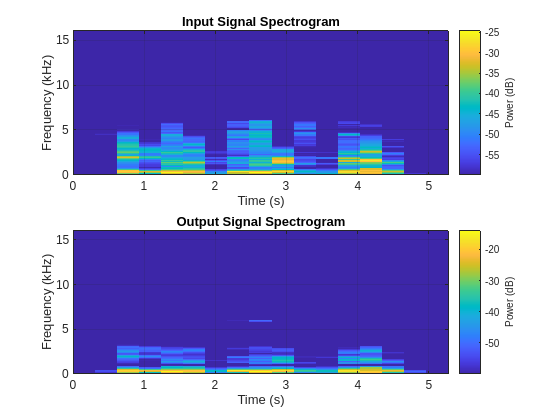

% Display spectrogram
figure;
subplot(2,1,1);
pspectrum(src, fs_dst, "spectrogram", 'TimeResolution', 0.31, 'OverlapPercent', 0, 'MinThreshold', -60);
title('Input Signal Spectrogram');
subplot(2,1,2);
pspectrum(dst, fs_dst, "spectrogram", 'TimeResolution', 0.31, 'OverlapPercent', 0, 'MinThreshold', -60);
title('Output Signal Spectrogram');

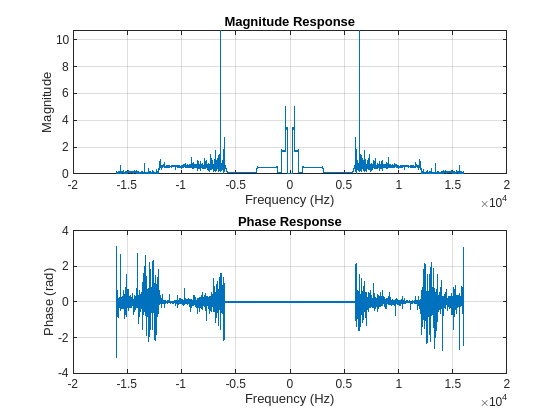

% Calculate frequency response
src_fft = fftshift(fft(src));
dst_fft = fftshift(fft(dst));
tf = dst_fft ./ src_fft;

figure;
subplot(2,1,1);
plot(f_dst, abs(tf));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Response');
subplot(2,1,2);
plot(f_dst, angle(tf));
xlabel('Frequency (Hz)');
ylabel('Phase (rad)');
title('Phase Response');